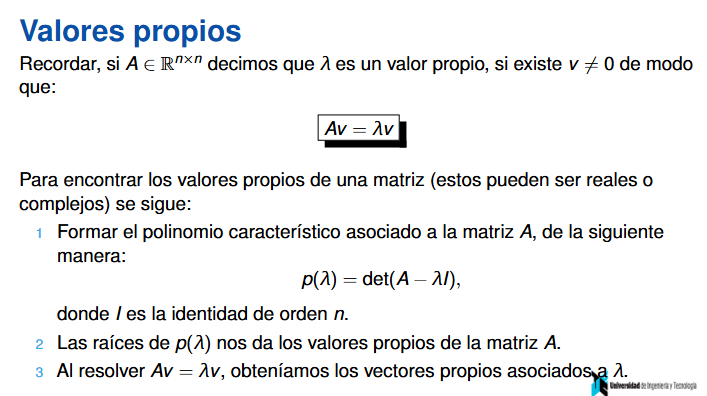

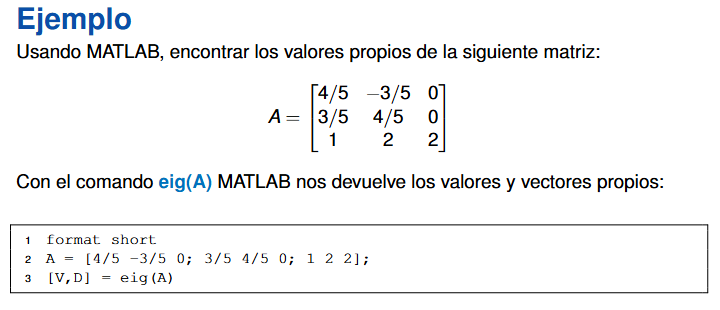

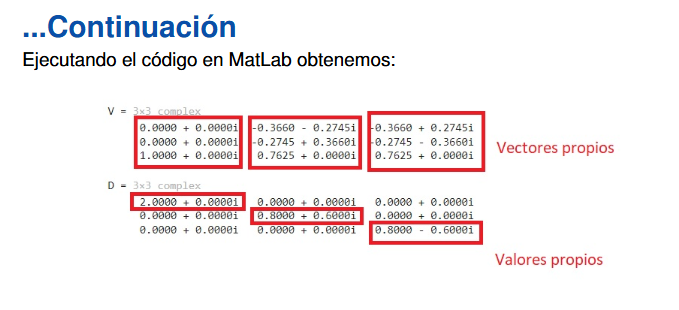

% Mostrar los resultados con pocos decimales
format short

% Ingresar la matriz A del ejercicio
A = [4/5 -3/5 0;
    3/5  4/5 0;
    1    2   2];

% Aplicar el comando eig para calcular valores y vectores propios
% V contiene los vectores propios por columnas
% D contiene los valores propios en la diagonal
[V,D] = eig(A);

% Mostrar los vectores propios
V

V =    0.0000 + 0.0000i   0.3660 + 0.2745i   0.3660 - 0.2745i
   0.0000 + 0.0000i   0.2745 - 0.3660i   0.2745 + 0.3660i
   1.0000 + 0.0000i  -0.7625 + 0.0000i  -0.7625 + 0.0000i



% Mostrar los valores propios
D

D =    2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.8000 + 0.6000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.8000 - 0.6000i


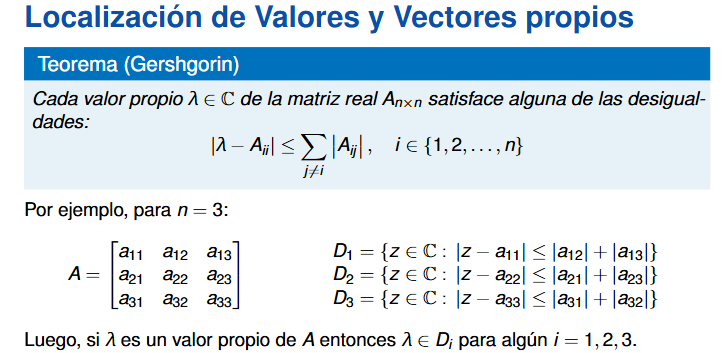

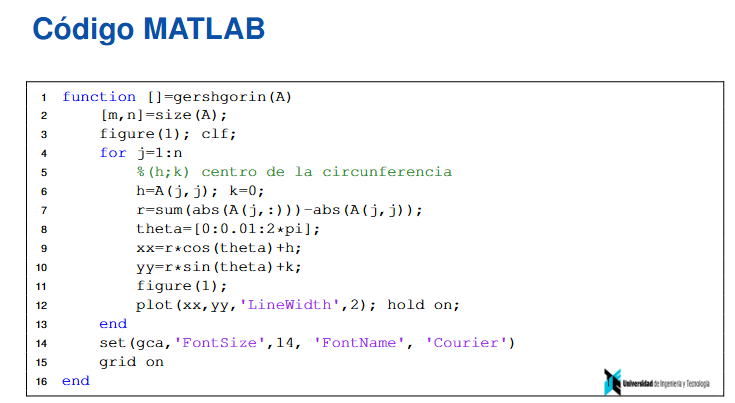

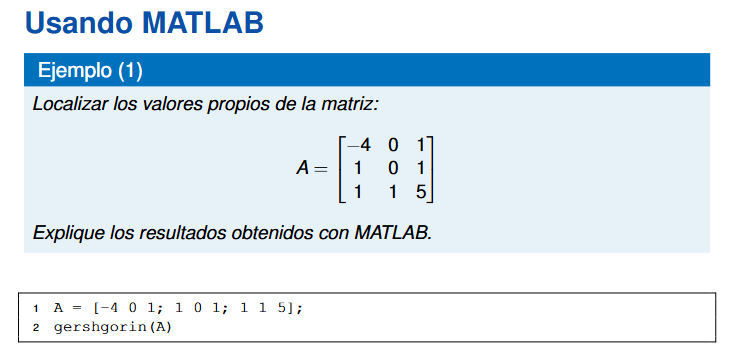

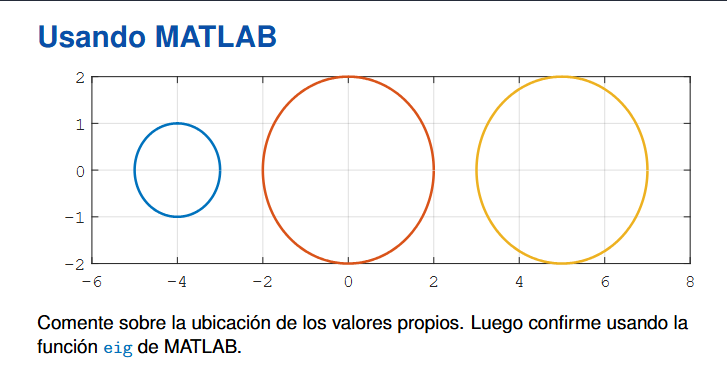

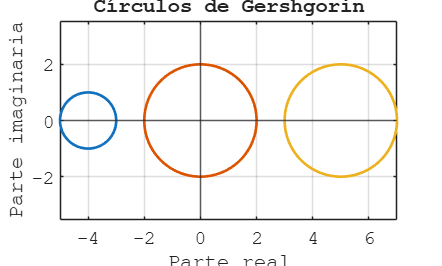

% Limpiar las variables almacenadas en el Workspace
clear

% Limpiar la ventana de comandos
clc

% Cerrar todas las figuras abiertas
close all

% Mostrar los resultados numéricos con formato corto
format short

% Definir la matriz A del ejercicio
A = [-4 0 1;
    1 0 1;
    1 1 5];

% Obtener el número de filas m y columnas n de la matriz A
[m,n] = size(A);

% Abrir una nueva figura y limpiar cualquier gráfico anterior
figure(1); clf;

% Recorrer cada fila de la matriz A
for j = 1:n

    % Definir el centro del círculo de Gershgorin como A(j,j)
    h = A(j,j);

    % Definir la coordenada vertical del centro igual a cero
    k = 0;

    % Calcular el radio como la suma de los valores absolutos
    % de los elementos de la fila, excluyendo el elemento diagonal
    r = sum(abs(A(j,:))) - abs(A(j,j));

    % Crear valores angulares desde 0 hasta 2*pi
    theta = 0:0.01:2*pi;

    % Calcular las coordenadas horizontales de la circunferencia
    xx = r*cos(theta) + h;

    % Calcular las coordenadas verticales de la circunferencia
    yy = r*sin(theta) + k;

    % Graficar el círculo de Gershgorin correspondiente a cada fila
    plot(xx,yy,'LineWidth',2); hold on;

end

% Configurar el tamaño y tipo de letra de los ejes
set(gca,'FontSize',14,'FontName','Courier')

% Activar la cuadrícula de la gráfica
grid on

% Colocar una línea horizontal que represente el eje real
yline(0)

% Colocar una línea vertical que represente el eje imaginario
xline(0)

% Colocar nombre al eje horizontal
xlabel('Parte real')

% Colocar nombre al eje vertical
ylabel('Parte imaginaria')

% Colocar título a la gráfica
title('Círculos de Gershgorin')

% Mantener la misma escala en ambos ejes
axis equal


% Calcular los vectores propios V y los valores propios D de la matriz A
[V,D] = eig(A);

% Mostrar la matriz de vectores propios
V

V =    -0.1045   -0.9725    0.0474
   -0.2028    0.2177   -0.9827
   -0.9736    0.0831    0.1788



% Mostrar la matriz diagonal que contiene los valores propios
D

D =     5.3157         0         0
         0   -4.0854         0
         0         0   -0.2302



% Extraer solamente los valores propios de la diagonal de D
lambda = diag(D);

% Mostrar los valores propios
lambda

lambda =     5.3157
   -4.0854
   -0.2302
